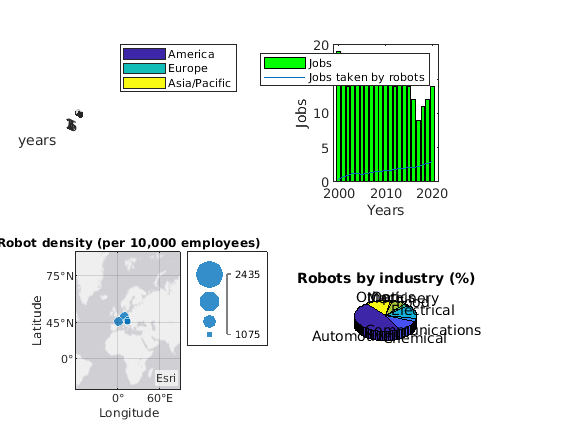

,% create first plot of installations per global area per year
subplot(2,2,1)

%create data vectors from excel file
Robots = [46	67	280; 55	75	283; 54	74	285; 59	79	320; 64	83	368; 69	87	420];
% plot using 3D bar graph
bar3(Robots)

% add labels
xlabel("countries")
ylabel('years')
zlabel('installations (x1000)')
legend({'America', 'Europe', 'Asia/Pacific'})

% create second plot describing job replacement by robots
Years = 2000:1:2020;
% data line vectors
Man = [19 18 14 15 18 16 15 17 16 18 17 16 14 15 15 14 12 9 11 12 14];
Ind = [0.4 0.8 1 1.2 1.3 1.15 1.2 1.4 1.55 1.6 1.7 1.75 1.8 1.95 2 2.05 2.1 2.2 2.5 2.7 3];
subplot(2,2,2)
% plot with bar and line on same graph
bar(Years, Man, 'g')

hold on
line(Years, Ind)
xlabel('Years')
ylabel('Jobs')
legend({'Jobs', "Jobs taken by robots"})

% create geobubble plot 

% define geographic vectors and relative density
Robodensity = [2435 1354 1200 1162 1158 1156 1083 1075];

Lat = [35.91 56.13 37.09 51.17 36.2 46.23 47.52 46.15];

Lon = [127.77 -106.35 -95.71 10.45 138.25 2.21 14.55 15];

subplot(2,2,3)
geobubble(Lat, Lon, Robodensity );
title('Robot density (per 10,000 employees)')

% create final plot of industry percentages
subplot(2,2,4)

percent = [33.2 8.4 2.3 9.9 1.5 5.3 0.8 9.2];
labels = [{'Automotive', 'Chemical', 'Communications', 'Electrical', 'Food', 'Machinery', 'Optics', 'Other'}];
pie3(percent, labels)
title("Robots by industry (%)")